# Getting Started with TTLEM

## System Requirements

TTLEM requires TopoToolbox and its dependencies. 

## Features

TTLEM is a landscape evolution model involving processes of rock uplift, hillslope denudation and river incision. These processes rely on highly simplified models such as the linear or nonlinear hillslope diffusion model for hillslopes or the stream-power incision model for river incision.

## Installation and Setup

## Getting started

TTLEM runs with real topographic data but often you will use synthetic data. For instance, you may start with an initially flat, randomly perturbed surface and block uplift to see how a fluvial landscape evolves over time.

cellsize = 100;
gridsize = [200 200]; % 200 rows and 200 columns
DEM = GRIDobj(randn(gridsize),cellsize);

Now we create a set of parameters that determine the stream power parameters, the diffusivity, but also parameters that control the numerics of the solvers.

p = ttlemset

p = struct with fields:
           AreaThresh: 0
              BC_Type: 'Dirichlet_Matrix_Ini'
     BC_dir_DistSites: ''
    BC_dir_Dist_Value: 1
         BC_dir_value: 0
           BC_nbGhost: 1
                    D: 0.0100
            DiffToRiv: 0
              DiffTol: 1.0000e-06
             DrainDir: 'variable'
               FlowBC: ''
             K_weight: []
                   Kw: 3.0000e-06
           NormPrecip: []
             SS_Value: 0
                   Sc: 1.2000
              Sc_unit: 'tangent'
             TimeSpan: 2000000
             TimeStep: 20000
                 cfls: 0.7000
           diffScheme: 'imp_lin_sc'
           fileprefix: 'res_'
              implCFL: 0
                    m: 0.5000
                m_var: 0
                    n: 1
             parallel: 0
             ploteach: 1
           resultsdir: 'results\'
               rho_rs: 1.3000
             riverInc: 'implicit_FDM'
             saveeach: Inf
              short_x: []
              s

Here, we change the parameter that determine the frequency at which a figure  is updated. If set to inf, there will be no figure.

p.ploteach = inf;

We also need to define an uplift pattern. Here, we have a uniform uplift of 0.0001 m/year. The edges of the DEM do not uplift.

U = GRIDobj(DEM);
U.Z(2:end-1,2:end-1) = 0.001;

Now we are ready to TTLEM.

T = ttlem(DEM,U,p);

TTLEM returns a structure array which may contain one or more GRIDobjs. In this example, this is only the final solution.

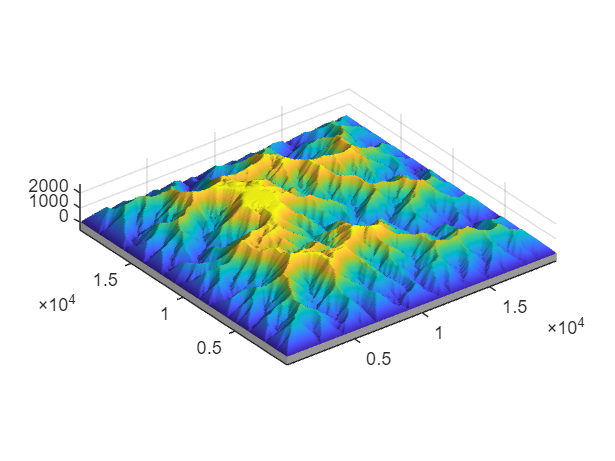

DEM1 = T.H1;
surf(DEM1,'block',true)
camlight; material dull